[~,p] = fit_logistic(time_E2,OD2)

p =   364.2289    1.1879    0.0096


t = 0:1200;
q = p(2)./(1+exp(-p(3)*(t-p(1))));
b = bar(time_E2, smell2, 'y')

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [1 1 0]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [0 23.0000 42.0000 460.0000 470 482.0000 492.0000 504.0000 863.0000 876.0000 888.0000 900.0000 911 925.0000 1089 1.1260e+03 1137]
        YData: [0 0 0 1.6667 1.5000 0.6667 1 1 1.6667 0.6667 1 1 1 0.3333 1 0 0]

  Show all properties


hold on
plot(t,q,'k');
plot(time_E2, OD2,'*','MarkerSize', 5,'MarkerEdgeColor','red');
xlabel('Time (min)')    
ylabel('OD600')
s=findobj('tag', 'legend')

s =   0×0 empty GraphicsPlaceholder array.


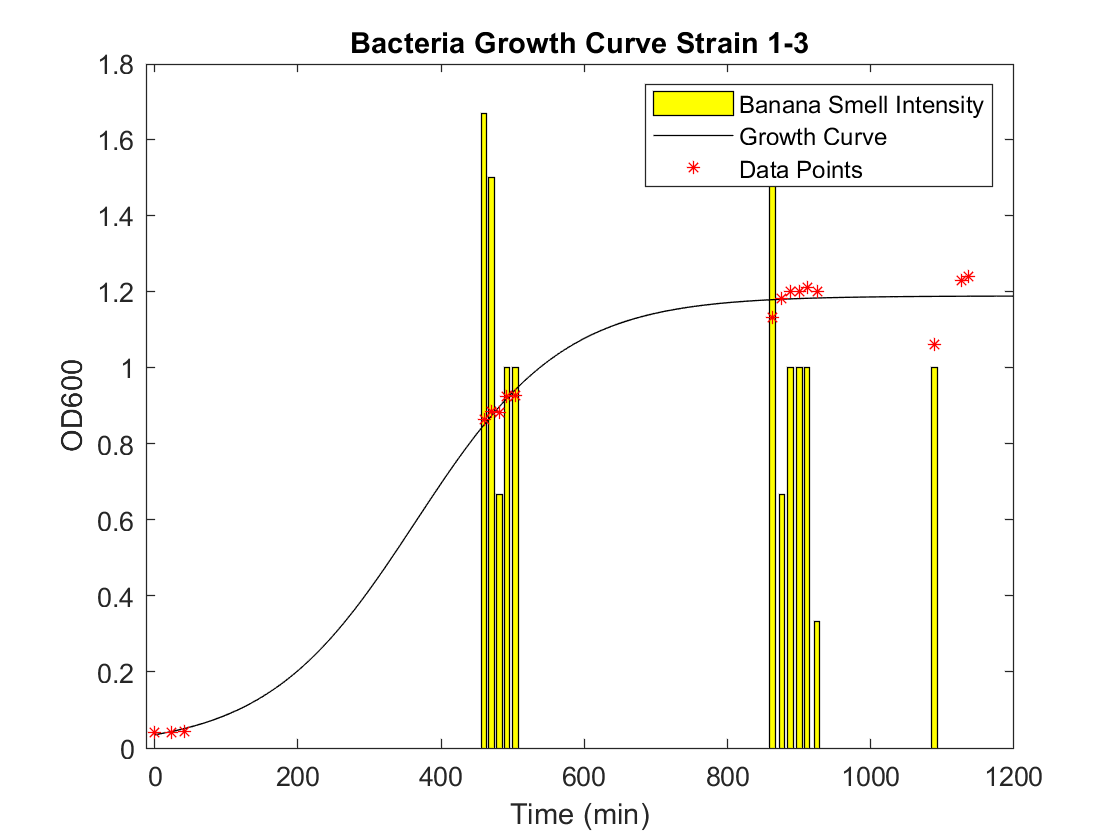


title('Bacteria Growth Curve Strain 1-3')

legend('Banana Smell Intensity','Growth Curve', 'Data Points')